## Exercise 1.

Write a function that calculates the correlation between two input vectors. Use only basic MATLAB functions (mean, std, ...). 

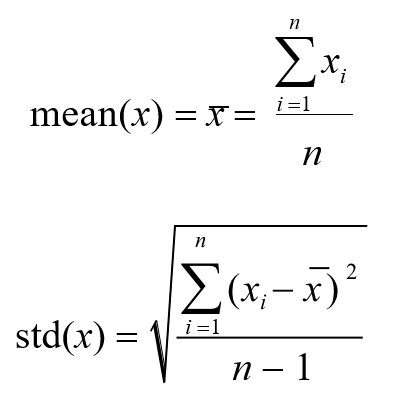      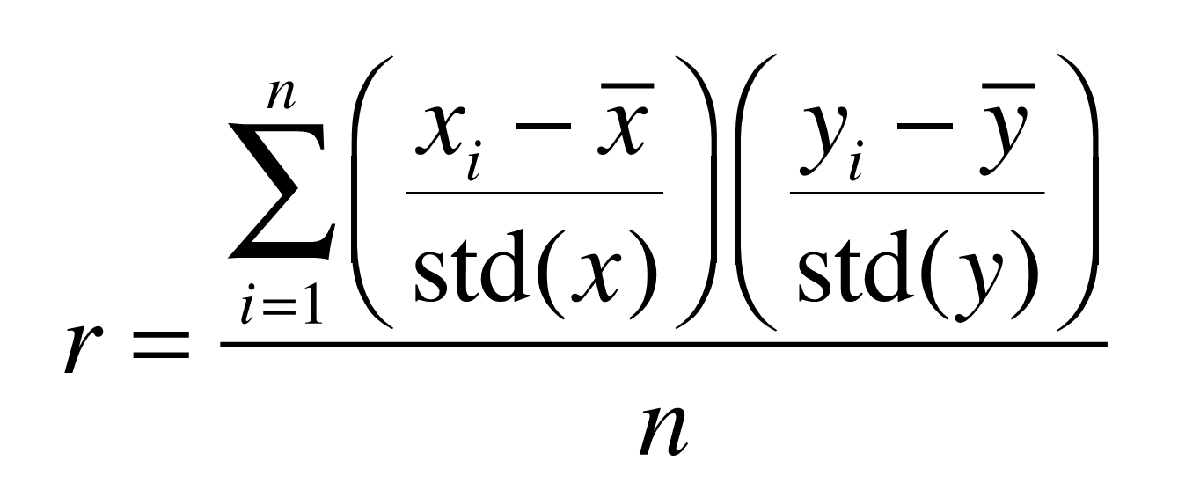

nVectorElements = 10000;
nRows = 1;

% Generate two vectors with normally distributed random values
vector1 = randn(nRows, nVectorElements);
vector2 = randn(nRows, nVectorElements);

% Calculate mean values for both of two vectors
vector1_mean = mean(vector1);
vector2_mean = mean(vector2);

% Calculate std values for both of two vectors
std_vector1 = std(vector1);
std_vector2 = std(vector2);

vec1 = (vector1 - vector1_mean) / std_vector1;
vec2 = (vector2 - vector2_mean) / std_vector2;

% Correlation value
r = mean(vec1 .* vec2);

fprintf("The correlation between two input vectors = %f", r);

The correlation between two input vectors = 0.001129

## Exercise 2.

Conduct Monte Carlo simulations in which samples are drawn from а Gaussian distribution with mean 10 and standard deviation 2. For each of various sample sizes (n = 2, 5, 10, 20, 50,100,200,500, 1000), draw 1,000 random samples, compute the mean of each sample, and quantify the spread in the results by computing standard deviation. Then make а line plot that shows the relationship between sample size (x-axis) and the uncertainty (spread) of the mean (y-axis). On the same figure, draw а line that shows the theoretical expectation.  

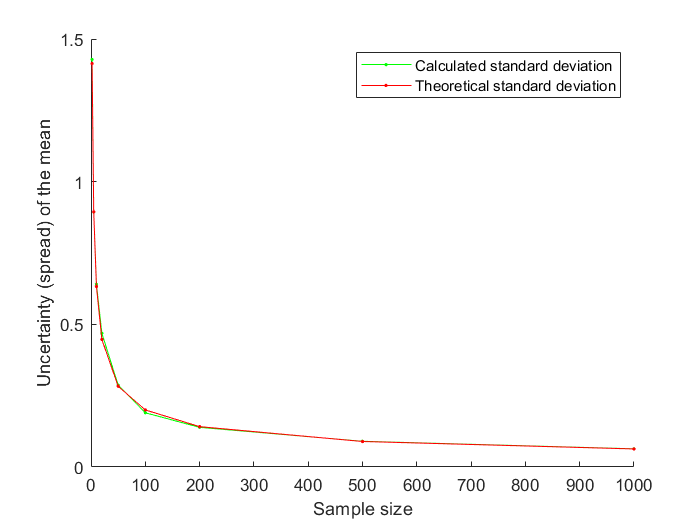

inputMean = 10;
inputStd = 2;

nSimulations = 1000;
sampleSizes = [2, 5, 10, 20, 50, 100, 200, 500, 1000];
nSampleSizes = length(sampleSizes);

% Pre-allocate the results vector
calculatedStd = zeros(1, nSampleSizes);
theoreticalStd = zeros(1, nSampleSizes);

% For each of various sample sizes
for sampleNum = 1:nSampleSizes
    means = zeros(1, nSimulations);
    
    % Monte Carlo simulation (loop over simulations)
    for simulationNum = 1:nSimulations
        % Generate sample vector with input mean and standard deviation
        sampleData = normrnd(inputMean, inputStd, [1, sampleSizes(sampleNum)]);
        
        % Calculate mean of generated sample vector
        means(simulationNum) = mean(sampleData);
    end
    
    calculatedStd(sampleNum) = std(means);
    theoreticalStd(sampleNum) = inputStd / sqrt(sampleSizes(sampleNum));
end

% Visualize the results
figure; 
hold on; % Retains the current plot and certain axes properties so that subsequent graphing commands add to the existing graph
l1 = plot(sampleSizes, calculatedStd,'g.-');
l2 = plot(sampleSizes, theoreticalStd,'r.-');
legend([l1 l2], {'Calculated standard deviation', 'Theoretical standard deviation'});
xlabel('Sample size');
ylabel('Uncertainty (spread) of the mean');

## Exercise 3.

Write a function that calculates that accepts an input vector and returns a new vector representing a boostrap sample drawn from the original vector.

% Randomly generated input original vector 
input = randn(1, 10);

% A new vector representing a boostrap sample drawn from the original vector
bootstrapped = my_bootstrap(input)

bootstrapped =     0.3676   -0.1694    0.0643    0.3676    0.3676    0.3676    0.0643    0.0643    2.0862   -0.1694


## Exercise 4.

Modify the function in Exercise 3 to accept another input specifying the number of bootstrap samples to draw. Then have the function return a 2D matrix with different boostrap samples in the columns of the matrix. Avoid the use of for-loops in this function so that the function is fast.

% Randomly generated input original vector 
input = randn(1, 10);

% 2D matrix with different boostrap samples in the columns of the matrix
bootstrapped_matrix = matrix_bootstrap(input, 2)

bootstrapped_matrix =     0.5065   -0.7328   -0.9368    0.6204   -0.7328   -0.9368   -0.7328    0.6204   -0.7603   -0.7603
   -0.4574   -0.9368   -0.7603   -0.4574   -0.7603   -1.3042   -0.4574    0.6204    0.6826   -0.0255


## Exercise 5.

Generate some correlated data (two variables). Visualize the data using а scatter plot. 

Then compute а 2D histogram of these data and visualize the histogram as an image. 

Compute the marginal distribution of the data (showing the distribution of the data on each variable separately) and then compute the joint distribution that we would expect to observe if the variabes were independent. Visualize this distribution as an image.

% Generate correlated data (two correlated vectors)

% https://uk.mathworks.com/matlabcentral/answers/101802-how-can-i-generate-two-correlated-random-vectors-with-values-drawn-from-a-normal-distribution

% Use input values from Exercise 2:
inputMean = 10;
inputStndDvtn = 2;

desiredCorr = 0.75;

% Generate a random matrix M with 2 columns (using RANDN) corresponding to the 2 vectors that are to exhibit the desired correlation
corrData = inputMean + inputStndDvtn * randn(1000, 2);

% Define the desired correlation in matrix R (0.75)
% R is trivially symmetric and positive definite
R = [1 desiredCorr; desiredCorr 1];
% Returns an upper triangular matrix L (such that L'*L = R)
L = chol(R);

% M is multiplied with L in order to set the desired correlation
corrData = corrData * L;

% Two correlated vectors: vector1, vector2 
vector1 = corrData(:, 1);
vector2 = corrData(:, 2);

% Verifying correlation between two vectors
fprintf('The correlation value is %f', corr(vector1, vector2));

The correlation value is 0.767782

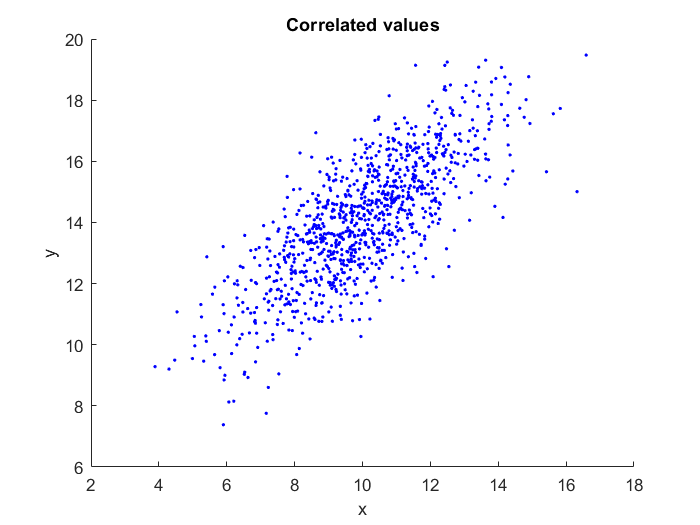

% Visualize data using a scatter plot
figure;
scatter(vector1, vector2, 'b.');
xlabel('x');
ylabel('y');
title('Correlated values');

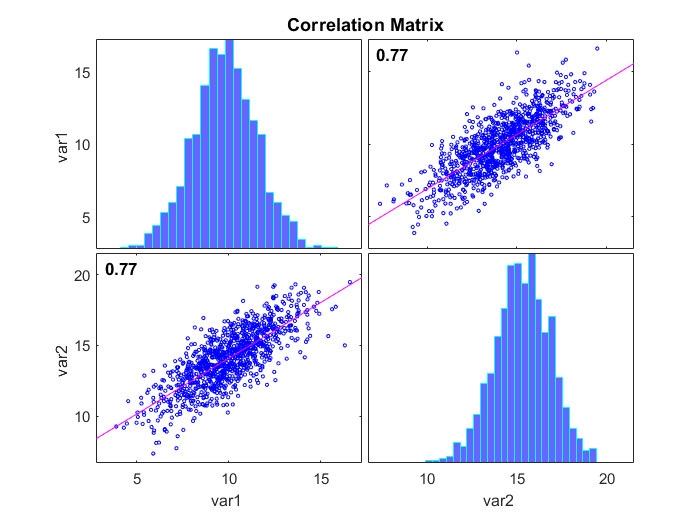

% Visualize thr variable correlations
% Along the diagonal - the histograms of the variables
% Along the off diagonal - the scatter plots of variable pairs
figure;
corrplot(corrData);

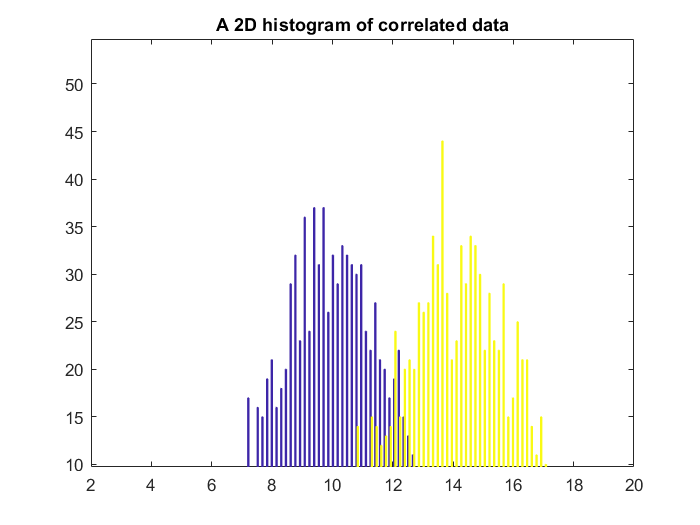

% A 2D histogram of generated data
figure;
hist(corrData, 100);
title('A 2D histogram of correlated data');

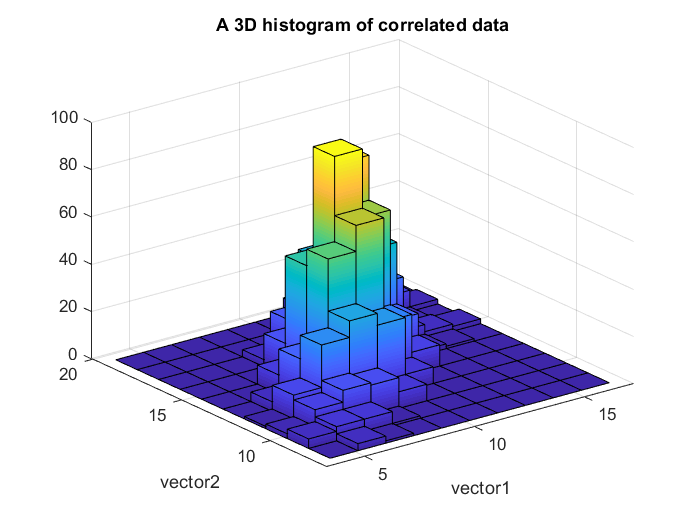

% A 3D histogram of generated data
% The height of each bar indicates the number of elements in bin
figure;
hist3(corrData, [100, 100], 'CDataMode', 'auto', 'FaceColor', 'interp');
xlabel('vector1');
ylabel('vector2');
title('A 3D histogram of correlated data');

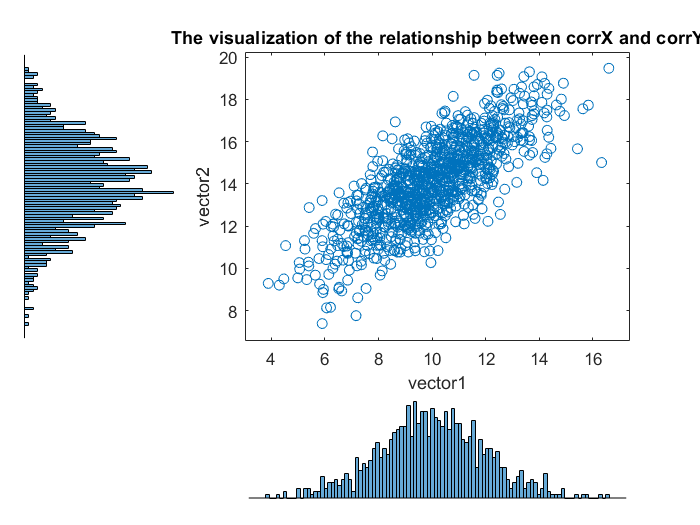

% 1. compute the marginal distribution of the data 
% for corrX and corrY variables separately -> 
% histograms on the horizontal and vertical axes of the scatter plot, respectively;
% 2. compute the joint distribution for corrX and corrY -> 
% the scatter plot;
figure;
scatterhist(vector1, vector2, 100);
xlabel('vector1');
ylabel('vector2');
title('The visualization of the relationship between vector1 and vector2');

# **Appendix**

Functions:

% Exercise 3


function results = my_bootstrap(input)
    in_length = length(input);
    
    % Take an randomized indexes to query from the original sample
    ix = ceil(in_length  * rand(1, in_length));
    
    % Return a vector chosen from the original one, but at random places
    results = input(ix);
end

% Exercise 4
function results = matrix_bootstrap(input, sample_num)
    in_length = length(input);
    
    % Take an randomized indexes to query from the original sample
    ix = ceil(in_length * rand(sample_num, in_length));
    
    % Return a vector chosen from the original one, but at random places
    results = input(ix);
end